# Analysis of the signals 

clc
clear variables
close all

% Settings
folder = 'chicken5x4x1cm';
dataType = 'bb';
dacMIN = 0;
dacMAX = 1400;
freq = 3;
variableName = strcat(dataType, num2str(dacMIN), '_', num2str(dacMAX), 'f', num2str(freq));
x = linspace(0.0, 9.9, 186);

% Radar Data
for i = -10:0
    fileName = strcat(folder, '/', num2str(i), 'cm.mat');
    objdata(i + 11) = load(fileName, variableName);
end

% Baseline
baseline = load(strcat(folder, '/', '-10cm.mat'), variableName);
% baseline = load(strcat('zero/baseline.mat'), variableName);
baseline = baseline.(variableName);
[width, length] = size(baseline);

baseline_mean = mean(baseline);
baseline_var = var(baseline);

clear dacMAX dacMIN dataType fileName folder freq i 

## Plot the original graphs

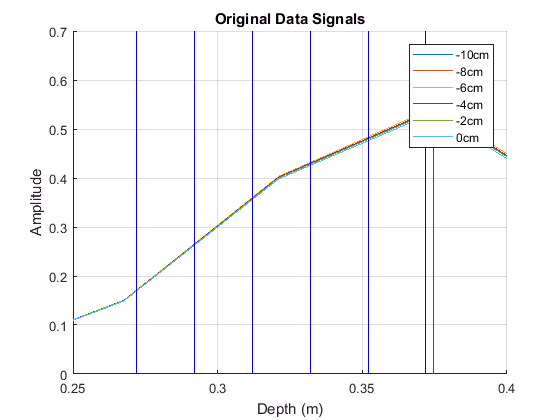

figure(1);
hax = axes;

hold on;
for i = [1, 3, 5, 7, 9, 11]
   p = objdata(i).(variableName);
   plot(x, abs(mean(p)));
end

[~, maxX] = max(mean(abs(p)));
line([x(maxX) x(maxX)], get(hax,'YLim'),'Color',[1 0 0]);
for i = [0,0.02,0.04,0.06,0.08,0.10]
    line([0.272+i 0.272+i], get(hax,'YLim'),'Color','blue');
end
legend({'-10cm','-8cm','-6cm','-4cm','-2cm','0cm'})
title('Original Data Signals')
xlabel('Depth (m)')
ylabel('Amplitude')
xlim([0.25, 0.4]);
grid on;

## Original Graphs - Baseline

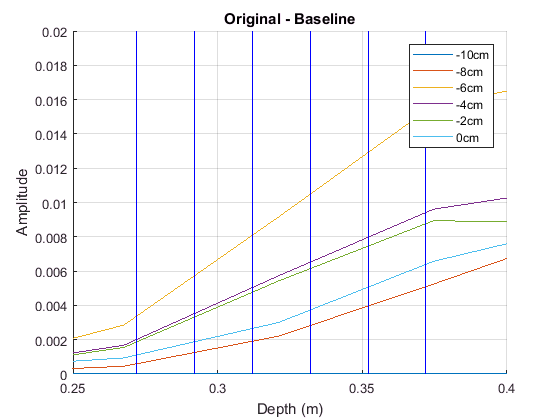

figure(2);
hax = axes;

hold on;
for i = [1, 3, 5, 7, 9, 11]
   p = objdata(i).(variableName);
   plot(x, abs(mean(p) - mean(baseline)));
end

for i = [0,0.02,0.04,0.06,0.08,0.10]
    line([0.272+i 0.272+i], get(hax,'YLim'),'Color','blue');
end

legend({'-10cm','-8cm','-6cm','-4cm','-2cm','0cm'})
title('Original - Baseline')
xlabel('Depth (m)')
ylabel('Amplitude')
xlim([0.25, 0.4]);
ylim([0, 0.02]);
grid on;

## Height of peak vs depth of chicken

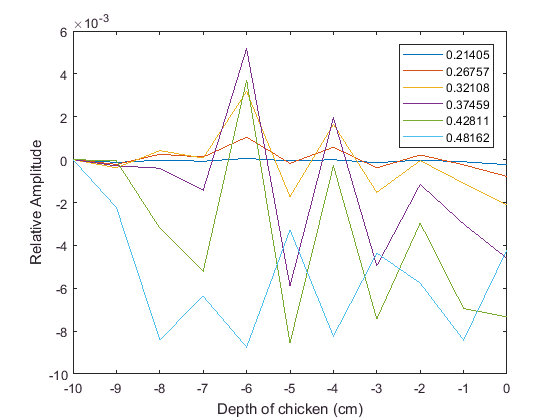

figure(3);
for d = 5:10
    depthc = -10:1:0;
    heightc = -10:1:0;
    for i = 1:11
        p = objdata(i).(variableName);
        heightc(i) = abs(mean(p(:, d))) ;
    end
    plot(depthc, heightc - heightc(1));
    hold on;
end
xlabel('Depth of chicken (cm)');
ylabel('Relative Amplitude');
xstr = string(x);
legend(xstr(5), xstr(6), xstr(7), xstr(8), xstr(9), xstr(10));

## Signal Noise Example

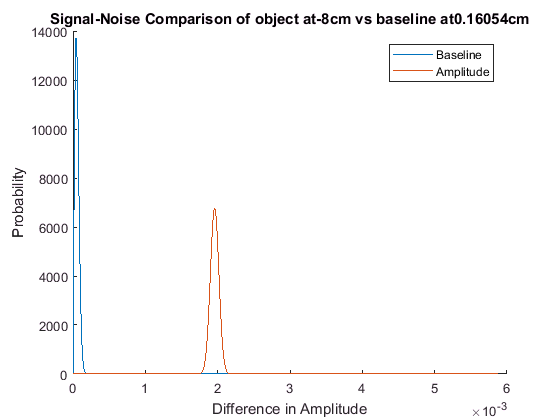

% Plot the SNR for a single point
figure(4);
bincount = 4;
distance = -8; % cm

baseline_var = var(baseline(:, bincount));
[s, sigma] = get_rician_param(objdata(distance + 11).(variableName)(:, bincount), baseline(bincount));

x2 = 0:sigma/10:s*3;
basepdf = pdf('Rayleigh', x2, sqrt(baseline_var));
newpdf = pdf('Rician', x2, s, sigma);
hold on;
plot(x2, basepdf);
plot(x2, newpdf);
hold off;

legend({'Baseline','Amplitude'});
title(strcat('Signal-Noise Comparison of object at ', num2str(distance), 'cm',' vs baseline at ', num2str(x(bincount)), 'cm'));
xlabel('Difference in Amplitude');
ylabel('Probability');

## Comparing the Signal to Noise Ratio from baseline

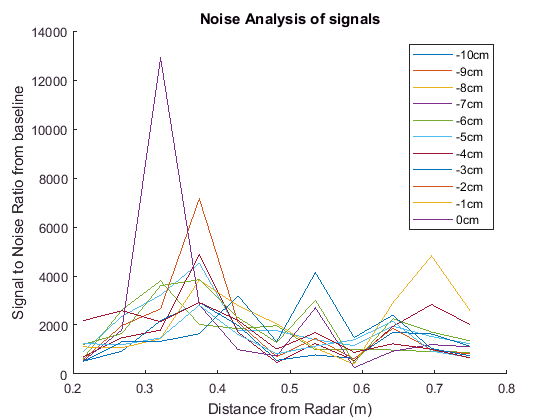

figure(5);
hold on;
xmin = 5;
xmax = 15;
obj_mean = zeros(11, xmax-xmin+1);
obj_var = zeros(11, xmax-xmin+1);
for i = 1:11
    [obj_mean(i, :), obj_var(i, :)] = get_rician_param(objdata(i).(variableName)(:, xmin:xmax), baseline(xmin:xmax));
    snr = abs(obj_mean(i, :))./obj_var(i, :);
    plot(x(xmin:xmax), snr);
end

xlabel('Distance from Radar (m)')
ylabel('Signal to Noise Ratio from baseline')
title('Noise Analysis of signals');
legend('-10cm', '-9cm','-8cm', '-7cm','-6cm', '-5cm','-4cm', '-3cm','-2cm', '-1cm','0cm')

# Functions

## Get Rician Parameters

function [s, variance] = get_rician_param(signal, baseline)
    subsignal = signal - mean(baseline);
    [l, w] = size(subsignal);
    s = zeros(1, w);
    variance = zeros(1, w);
    warning off;
    for i = 1:w
        try % There was a problem with the Rician
            dist = fitdist(abs(subsignal(:, i)), 'Rician');
        catch
            % s(i) = mean(abs(subsignal(:, i)));
            % variance(i) = var(abs(subsignal(:, i)));
            continue;
        end
        s(i) = dist.s;
        variance(i) = dist.sigma;
    end
    warning on;
end